#                                        MATH-131 Discussion                                       

**Feb 25, 2022**

**Mohammed Aburidi**

## Review

### Piecewise Linear Interpolation, first degree spline      

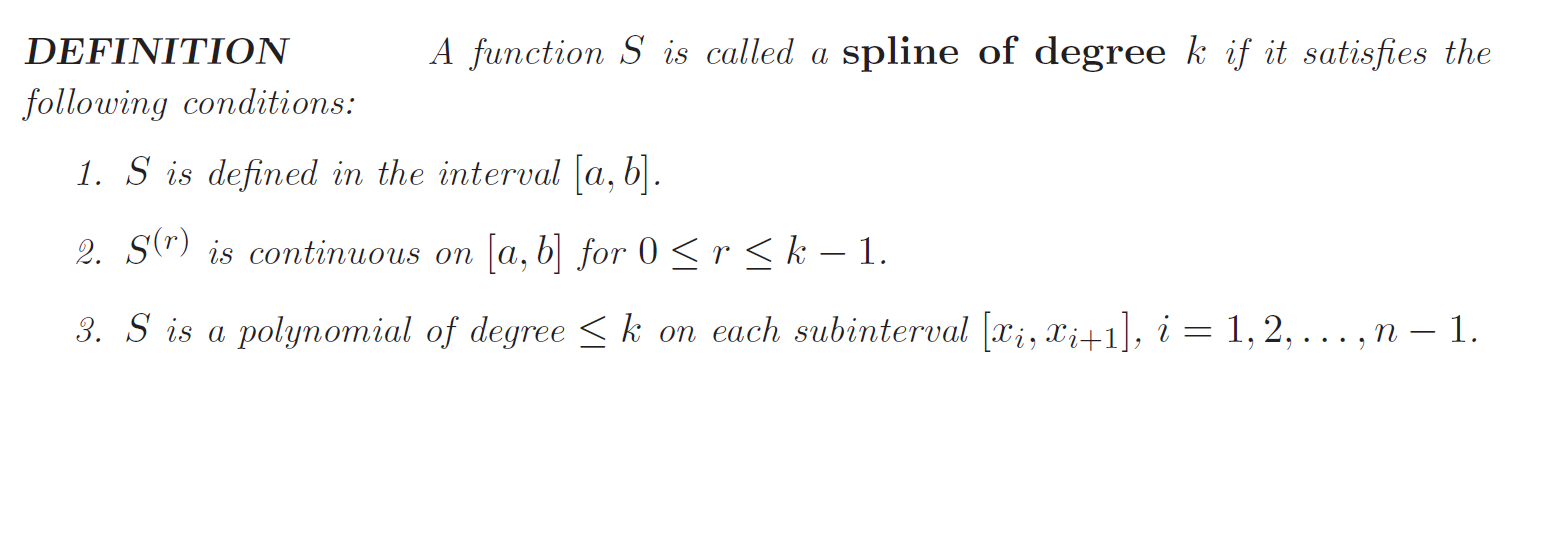

Note that:

- The degree of the spline does not increase with the number of points

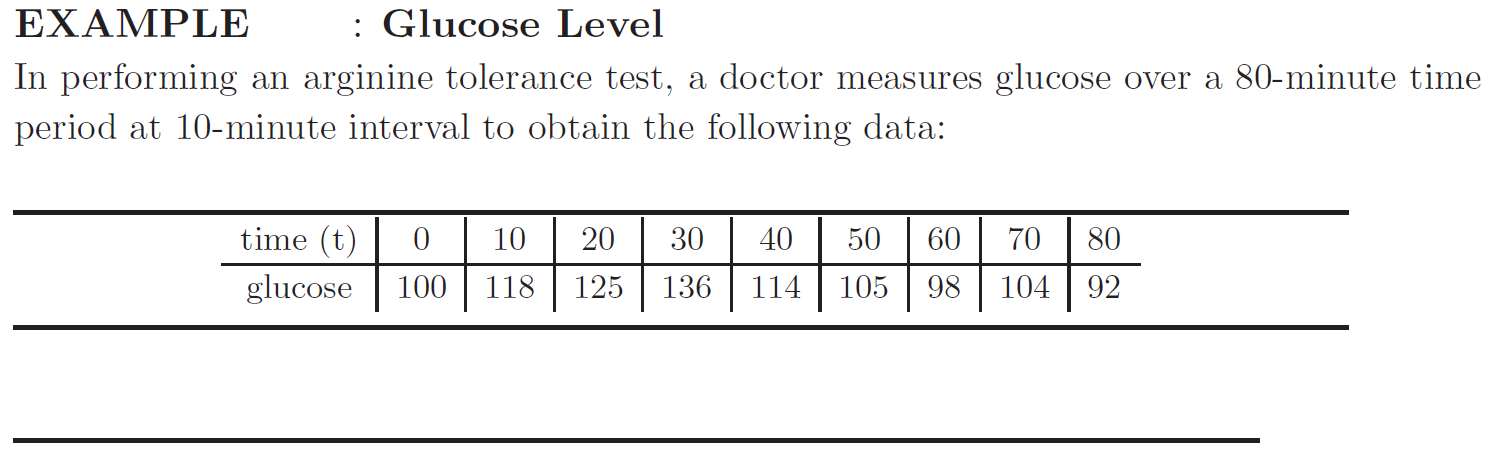

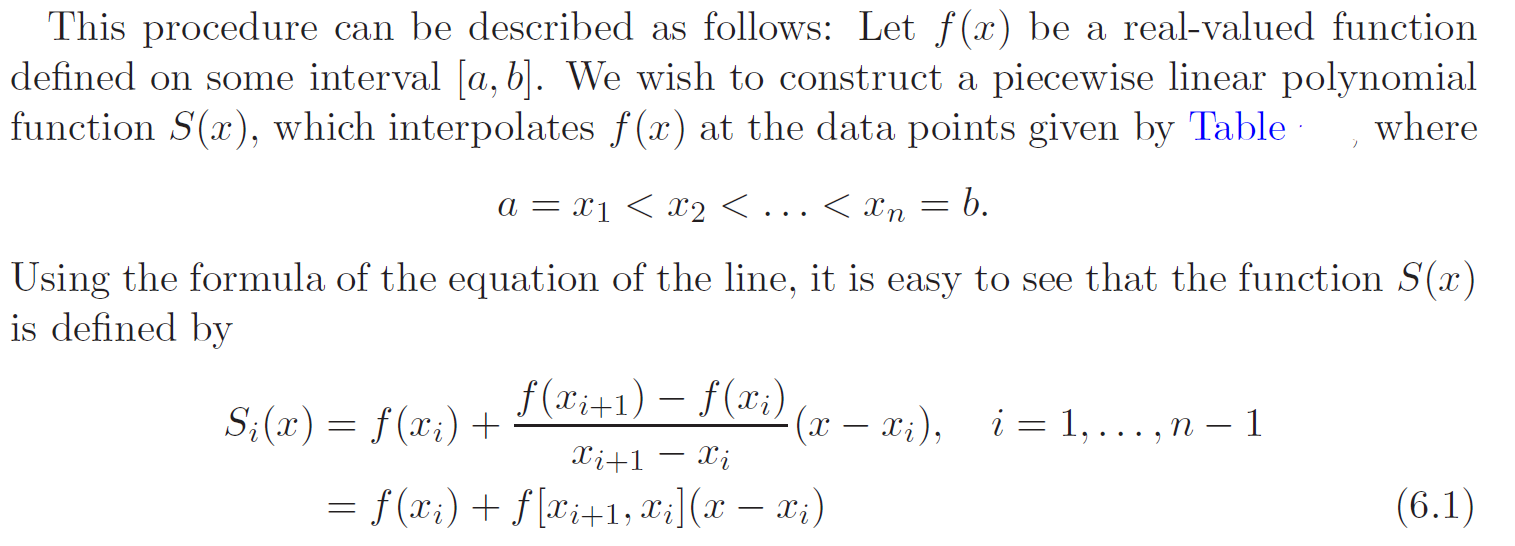

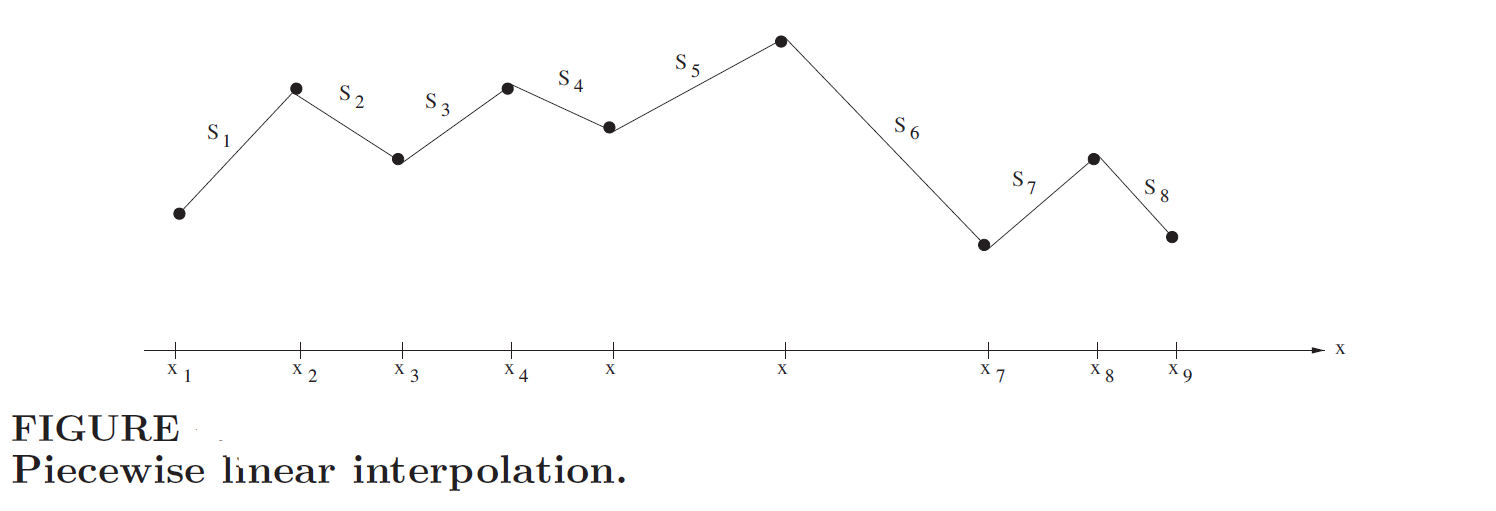

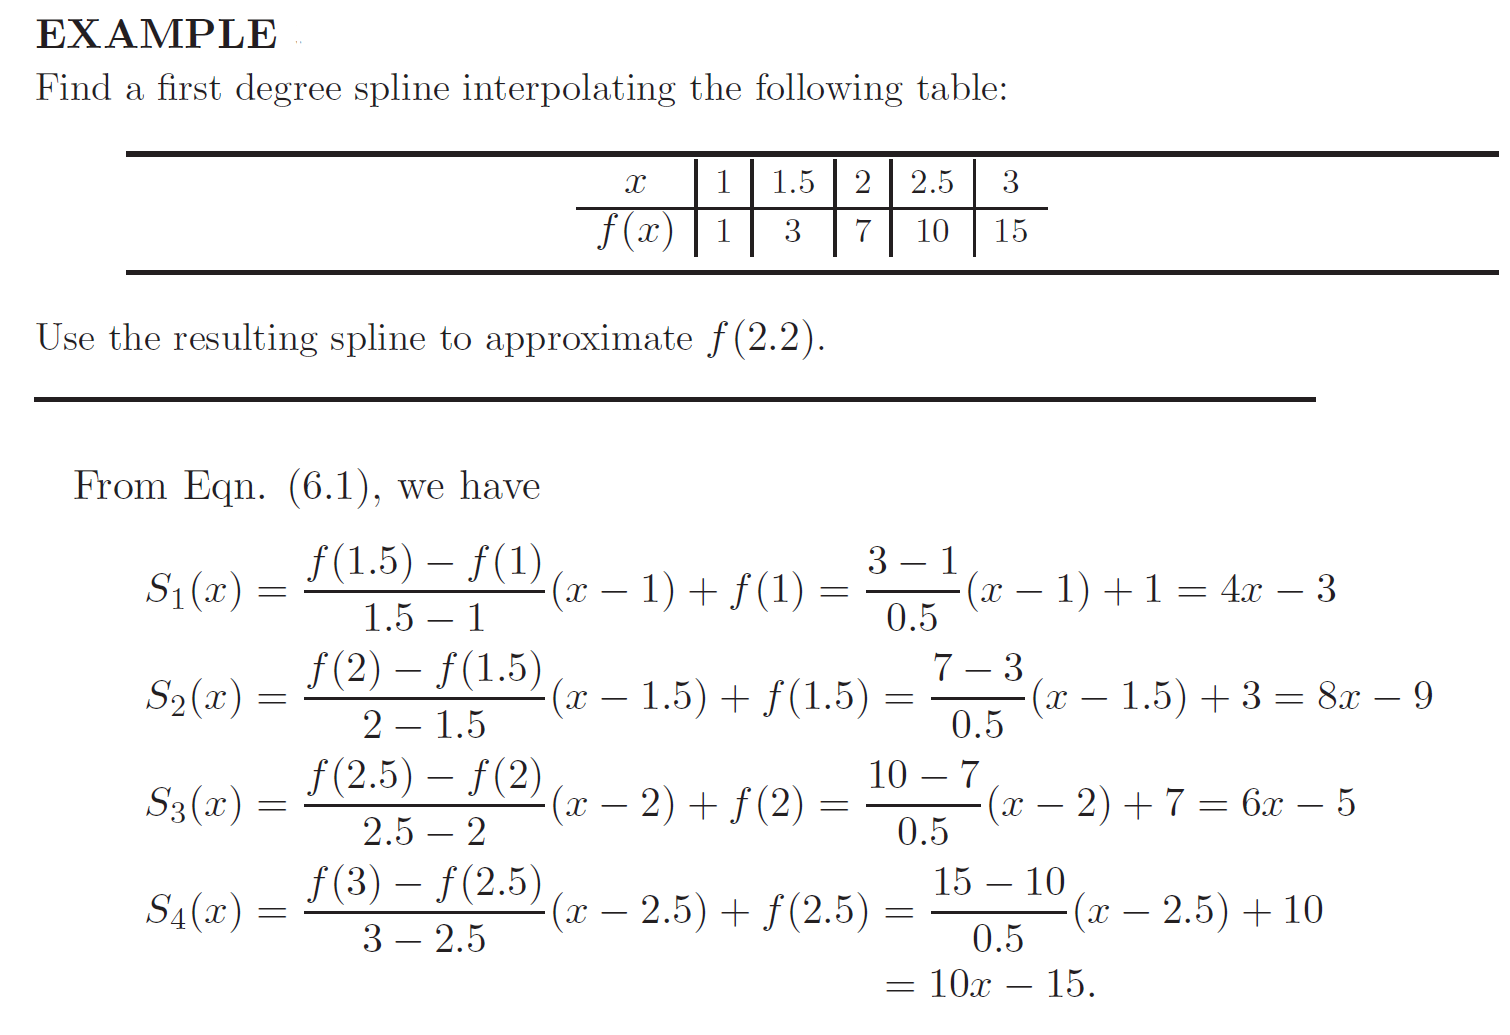

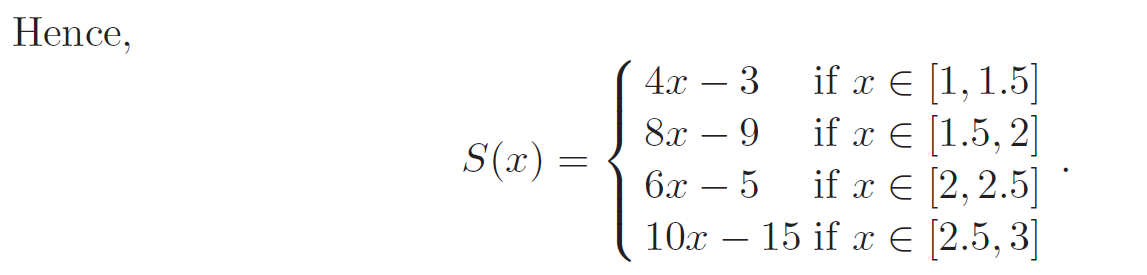

### Cubic Spline Interpolation    

## Coding Exercises 

The goal of this section is to get familiar with Cubic Spline Interpolation 

clc; close all; clear; 

### Problem 1: Natural Cubic Spline Interpolation 

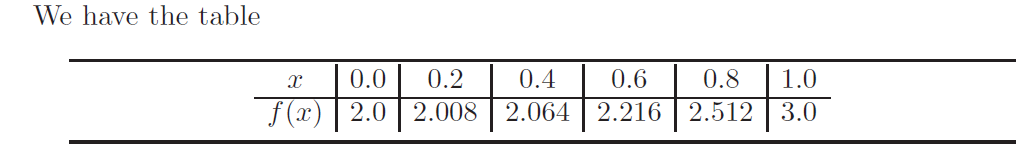

Use the MATLAB function  spline() to interpolate the x values 

% code here 
x = [0.0 0.2 0.4 0.6 0.8 1.0];
y = [2.0 2.008 2.064 2.216 2.512 3.0];
approx = 0:0.1:2;

y_inte = spline(x,y, approx);
f = @(x) x.^3 + 2;
fy = f(approx);
% disp(fy);
% disp(y_inte);

Plot the funciton and the interploated points

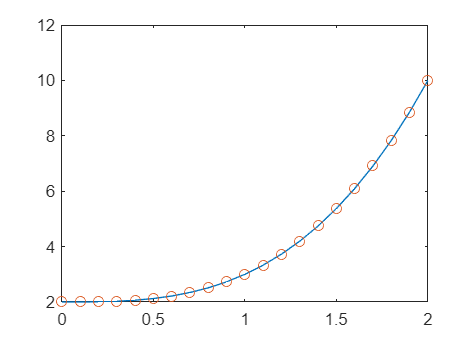

% code here 
plot(approx,fy,approx, y_inte,'o');

Lets see how it works: 

We calculated the following the coefficients (See below the pseudocode): 

c = [0.0, 0.586, 1.257, 1.585, 3.204]

a = [2, 2.008, 2.064, 2.216, 2.512]

b = [0.001, 0.118, 0.487, 1.055, 2.013] 

d =[0.976, 1.120, 0.545, 2.699, −5.340] 

notice that, I am looking for the follwing piecewise functoin:

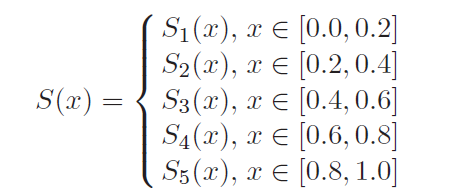

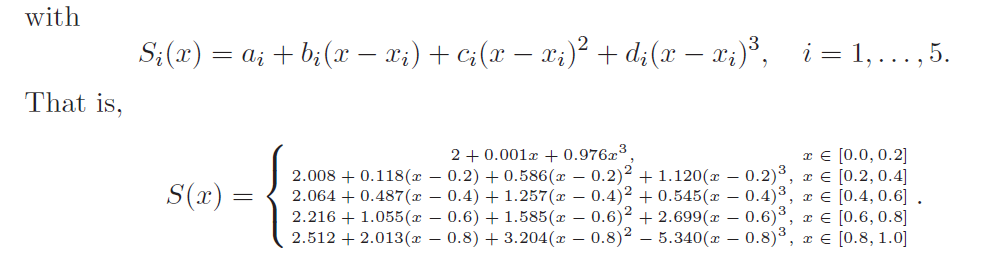

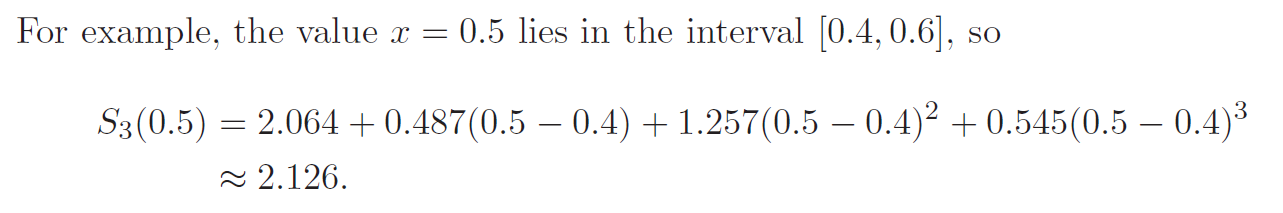

Write a Matlab function of Cubic Spline Method and interploate the x values x = 0.1, 0.3, 0.5, 0.7

% code here 

%input

x =[0.1 0.3 0.5 0.7]

x =     0.1000    0.3000    0.5000    0.7000



xdat = [0.0 0.2 0.4 0.6 0.8 1.0];
ydat = [2.0 2.008 2.064 2.216 2.512 3.0];

%-------
c = [0.0, 0.586, 1.257, 1.585, 3.204, 0.0];
a = [2, 2.008, 2.064, 2.216, 2.512];
b = [0.001, 0.118, 0.487, 1.055, 2.013]; 
d =[0.976, 1.120, 0.545, 2.699, -5.340]; 

N = length(xdat);
Sp =[];
x_p = [];

for m=1:N-1
    xx = xdat(m):0.1: xdat(m+1) - 0.1;
    Sp = a(m) + b(m) * (xx - xdat(m)) + c(m) * (xx - xdat(m)).^2 + d(m) * (xx - xdat(m)).^3;
    Sp = [Sp, Sp];
    x_p = [x_p,xx];
end


Plot the function and the interploated data 

% code here 
disp(length(x_p));

    10



disp(length(Sp));

     4



Plot the error 

% write your code here 


### Appendix